clear all
clear

fileName = 'DHPC.xlsx'; % Replace with your file name
opts.Sheet = 'Folha1';

dataArray = readmatrix(fileName, 'Sheet','Folha1');

chunk_size = dataArray(3, 4:14);

serial = dataArray(4:7, 38);

%Dynamic

Manldelbrot_dynamic = dataArray(4, 4:14);
Julia_dynamic = dataArray(5, 4:14);
Tricorn_dynamic = dataArray(6, 4:14);
Cosine_dynamic = dataArray(7, 4:14);

Manldelbrot_speedup_dynamic = serial(1,1)./Manldelbrot_dynamic;
Julia_speedup_dynamic = serial(2,1)./Julia_dynamic;
Tricorn_speedup_dynamic = serial(3,1)./Tricorn_dynamic;
Cosine_speedup_dynamic = serial(4,1)./Cosine_dynamic;

%Static

Manldelbrot_static = dataArray(4, 15:25);
Julia_static = dataArray(5, 15:25);
Tricorn_static = dataArray(6, 15:25);
Cosine_static = dataArray(7, 15:25);

Manldelbrot_speedup_static = serial(1,1)./Manldelbrot_static;
Julia_speedup_static = serial(2,1)./Julia_static;
Tricorn_speedup_static = serial(3,1)./Tricorn_static;
Cosine_speedup_static = serial(4,1)./Cosine_static;

%Guided

Manldelbrot_guided = dataArray(4, 26:36);
Julia_guided = dataArray(5, 26:36);
Tricorn_guided = dataArray(6, 26:36);
Cosine_guided = dataArray(7, 26:36);

Manldelbrot_speedup_guided = serial(1,1)./Manldelbrot_guided;
Julia_speedup_guided = serial(2,1)./Julia_guided;
Tricorn_speedup_guided = serial(3,1)./Tricorn_guided;
Cosine_speedup_guided = serial(4,1)./Cosine_guided;

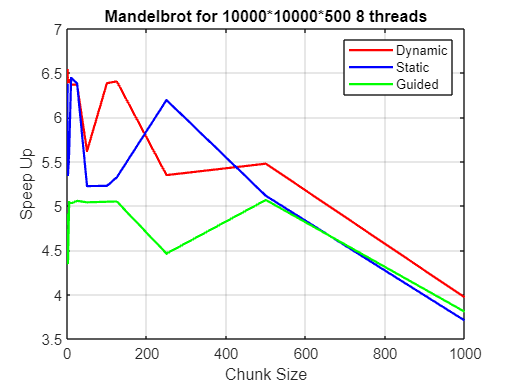

%Plot Mandlebrot

% Data for plotting
x = chunk_size; % X-axis values
y1 = Manldelbrot_speedup_dynamic;           
y2 = Manldelbrot_speedup_static;              
y3 = Manldelbrot_speedup_guided;           


% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red
plot(x, y2, '-b', 'LineWidth', 1.5);          % Line 2: Blue
plot(x, y3, '-g', 'LineWidth', 1.5);          % Line 3: Green


% Add labels and title
xlabel('Chunk Size');         % X-axis label
ylabel('Speep Up');         % Y-axis label
title('Mandelbrot for 10000*10000*500 8 threads');  % Title of the plot

% Add legend
legend('Dynamic', 'Static', 'Guided', 'Location', 'best');

% Display grid
grid on;

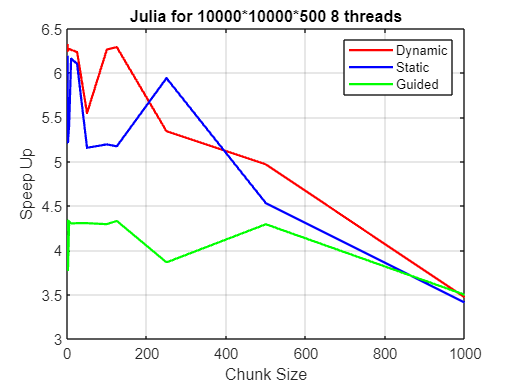

%Plot Julia

% Data for plotting
x = chunk_size; % X-axis values
y1 = Julia_speedup_dynamic;           
y2 = Julia_speedup_static;              
y3 = Julia_speedup_guided;           


% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red
plot(x, y2, '-b', 'LineWidth', 1.5);          % Line 2: Blue
plot(x, y3, '-g', 'LineWidth', 1.5);          % Line 3: Green


% Add labels and title
xlabel('Chunk Size');         % X-axis label
ylabel('Speep Up');         % Y-axis label
title('Julia for 10000*10000*500 8 threads');  % Title of the plot

% Add legend
legend('Dynamic', 'Static', 'Guided', 'Location', 'best');

% Display grid
grid on;

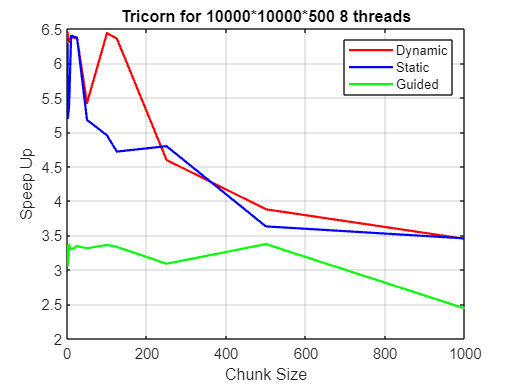

%Plot Tricorn

% Data for plotting
x = chunk_size; % X-axis values
y1 = Tricorn_speedup_dynamic;           
y2 = Tricorn_speedup_static;              
y3 = Tricorn_speedup_guided;           


% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red
plot(x, y2, '-b', 'LineWidth', 1.5);          % Line 2: Blue
plot(x, y3, '-g', 'LineWidth', 1.5);          % Line 3: Green


% Add labels and title
xlabel('Chunk Size');         % X-axis label
ylabel('Speep Up');         % Y-axis label
title('Tricorn for 10000*10000*500 8 threads');  % Title of the plot

% Add legend
legend('Dynamic', 'Static', 'Guided', 'Location', 'best');

% Display grid
grid on;

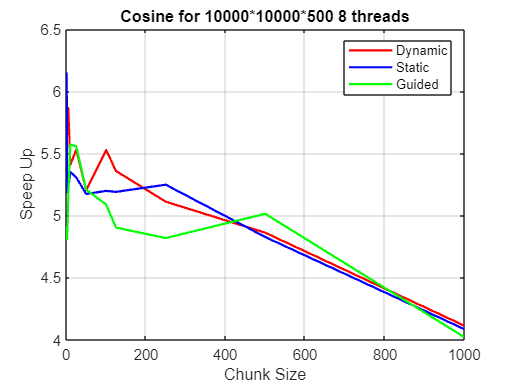

%Plot Cosine

% Data for plotting
x = chunk_size; % X-axis values
y1 = Cosine_speedup_dynamic;           
y2 = Cosine_speedup_static;              
y3 = Cosine_speedup_guided;           


% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red
plot(x, y2, '-b', 'LineWidth', 1.5);          % Line 2: Blue
plot(x, y3, '-g', 'LineWidth', 1.5);          % Line 3: Green


% Add labels and title
xlabel('Chunk Size');         % X-axis label
ylabel('Speep Up');         % Y-axis label
title('Cosine for 10000*10000*500 8 threads');  % Title of the plot

% Add legend
legend('Dynamic', 'Static', 'Guided', 'Location', 'best');

% Display grid
grid on;

ntreads = dataArray(14, 4:25);

serial = dataArray(41:44, 4);

Manldelbrot = dataArray(15, 4:25);
Julia = dataArray(16, 4:25);
Tricorn = dataArray(17, 4:25);
Cosine = dataArray(18, 4:25);

Manldelbrot_speedup = serial(1,1)./Manldelbrot;
Julia_speedup = serial(2,1)./Julia;
Tricorn_speedup = serial(3,1)./Tricorn;
Cosine_speedup = serial(4,1)./Cosine;

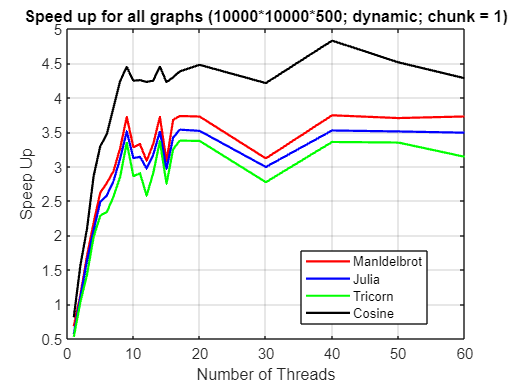

%Plot Cosine

% Data for plotting
x = ntreads; % X-axis values
y1 = Manldelbrot_speedup;           
y2 = Julia_speedup;              
y3 = Tricorn_speedup;
y4 = Cosine_speedup;


% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red
plot(x, y2, '-b', 'LineWidth', 1.5);          % Line 2: Blue
plot(x, y3, '-g', 'LineWidth', 1.5);          % Line 3: Green
plot(x, y4, 'k', 'LineWidth', 1.5);         

% Add labels and title
xlabel('Number of Threads');         % X-axis label
ylabel('Speep Up');         % Y-axis label

title('Speed up for all graphs (10000*10000*500; dynamic; chunk = 1)')

% Add legend
legend('Manldelbrot', 'Julia', 'Tricorn', 'Cosine', 'Location', 'best');

% Display grid
grid on;

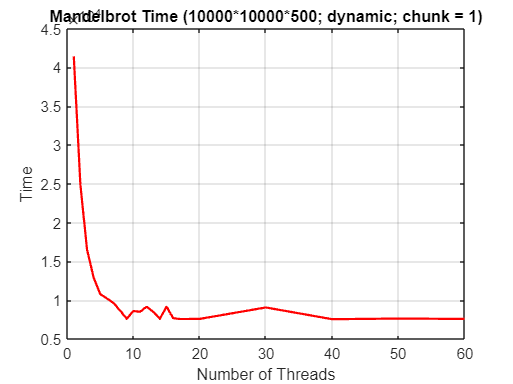

%Plot Cosine

% Data for plotting
x = ntreads; % X-axis values
y1 = Manldelbrot;           

% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red

% Add labels and title
xlabel('Number of Threads');         % X-axis label
ylabel('Time');         % Y-axis label
title('Mandelbrot Time (10000*10000*500; dynamic; chunk = 1)')

% Display grid
grid on;

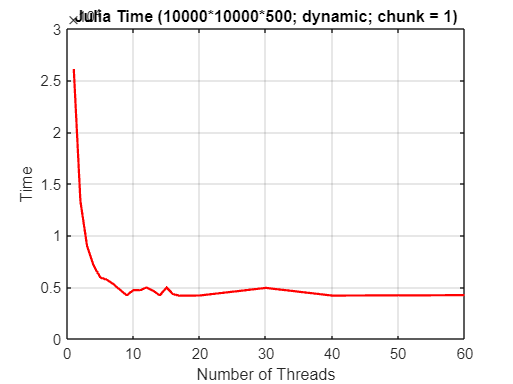

%Plot Cosine

% Data for plotting
x = ntreads; % X-axis values
y1 = Julia;           

% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red

% Add labels and title
xlabel('Number of Threads');         % X-axis label
ylabel('Time');         % Y-axis label
title('Julia Time (10000*10000*500; dynamic; chunk = 1)')

% Display grid
grid on;

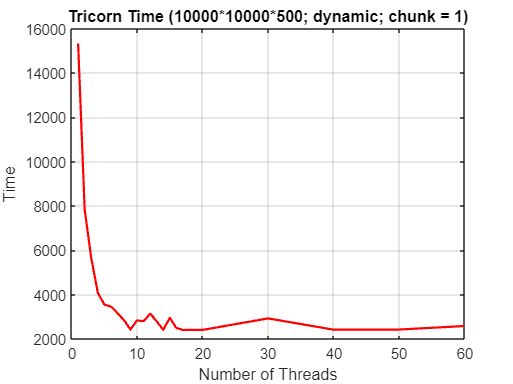

%Plot Cosine

% Data for plotting
x = ntreads; % X-axis values
y1 = Tricorn;           

% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red

% Add labels and title
xlabel('Number of Threads');         % X-axis label
ylabel('Time');         % Y-axis label
title('Tricorn Time (10000*10000*500; dynamic; chunk = 1)')

% Display grid
grid on;

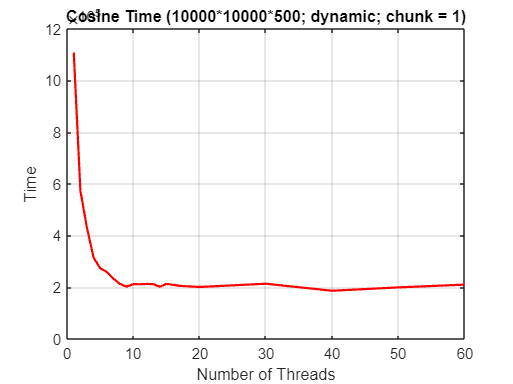

%Plot Cosine

% Data for plotting
x = ntreads; % X-axis values
y1 = Cosine;           

% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red

% Add labels and title
xlabel('Number of Threads');         % X-axis label
ylabel('Time');         % Y-axis label
title('Cosine Time (10000*10000*500; dynamic; chunk = 1)')

% Display grid
grid on;

ntreads_server = dataArray(33, 4:47);

serial_server = dataArray(41:44, 4);

Manldelbrot_server = dataArray(34, 4:47);
Julia_server = dataArray(35, 4:47);
Tricorn_server = dataArray(36, 4:47);
Cosine_server = dataArray(37, 4:47);

Manldelbrot_speedup_server = serial_server(1,1)./Manldelbrot_server;
Julia_speedup_server = serial_server(2,1)./Julia_server;
Tricorn_speedup_server = serial_server(3,1)./Tricorn_server;
Cosine_speedup_server = serial_server(4,1)./Cosine_server;

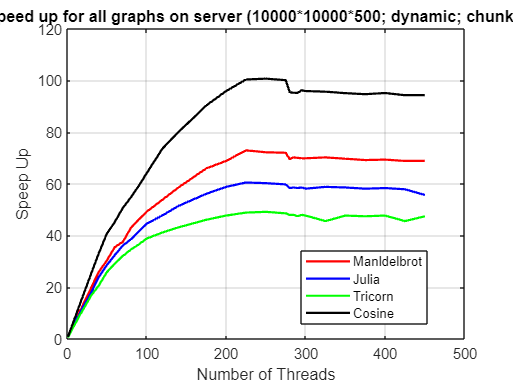

%Plot speed up

% Data for plotting
x = ntreads_server; % X-axis values
y1 = Manldelbrot_speedup_server;           
y2 = Julia_speedup_server;              
y3 = Tricorn_speedup_server;
y4 = Cosine_speedup_server;


% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red
plot(x, y2, '-b', 'LineWidth', 1.5);          % Line 2: Blue
plot(x, y3, '-g', 'LineWidth', 1.5);          % Line 3: Green
plot(x, y4, 'k', 'LineWidth', 1.5);         

% Add labels and title
xlabel('Number of Threads');         % X-axis label
ylabel('Speep Up');         % Y-axis label

title('Speed up for all graphs on server (10000*10000*500; dynamic; chunk = 1)')

% Add legend
legend('Manldelbrot', 'Julia', 'Tricorn', 'Cosine', 'Location', 'best');

% Display grid
grid on;

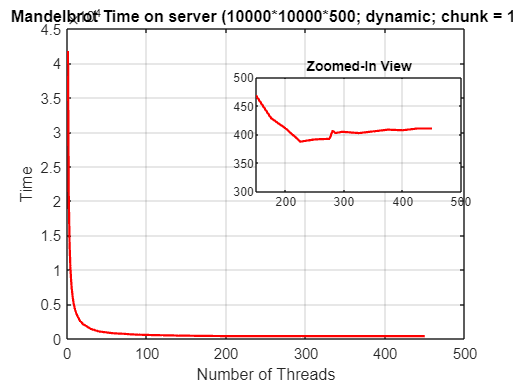

%Plot Mandelbrot

% Data for plotting
x = ntreads_server; % X-axis values
y1 = Manldelbrot_server;           

% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red

% Add labels and title
xlabel('Number of Threads');         % X-axis label
ylabel('Time');         % Y-axis label
title('Mandelbrot Time on server (10000*10000*500; dynamic; chunk = 1)')

% Display grid
grid on;

% Add zoomed-in inset
axes('Position', [0.5 0.5 0.4 0.3]); % Adjust position [x y width height]
box on; % Add a box around the inset
plot(x, y1, '-r', 'LineWidth', 1.5); % Plot the same data
xlim([150 500]); % Set zoomed-in x-axis range (adjust as needed)
ylim([300 500]); % Set zoomed-in y-axis range (adjust as needed)
title('Zoomed-In View'); % Title for the inset

% Add grid to the inset as well, if desired
grid on;

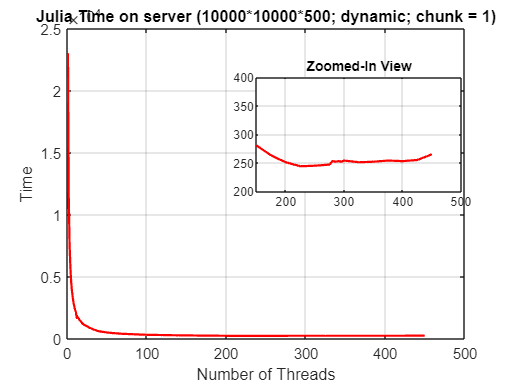

%Plot Julia

% Data for plotting
x = ntreads_server; % X-axis values
y1 = Julia_server;           

% Create the plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red

% Add labels and title
xlabel('Number of Threads');         % X-axis label
ylabel('Time');         % Y-axis label
title('Julia Time on server (10000*10000*500; dynamic; chunk = 1)')

% Display grid
grid on;

% Add zoomed-in inset
axes('Position', [0.5 0.5 0.4 0.3]); % Adjust position [x y width height]
box on; % Add a box around the inset
plot(x, y1, '-r', 'LineWidth', 1.5); % Plot the same data
xlim([150 500]); % Set zoomed-in x-axis range (adjust as needed)
ylim([200 400]); % Set zoomed-in y-axis range (adjust as needed)
title('Zoomed-In View'); % Title for the inset

% Add grid to the inset as well, if desired
grid on;

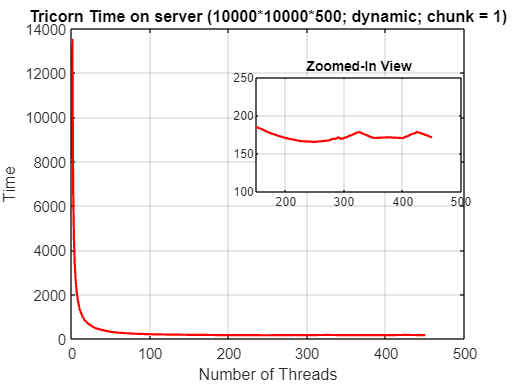

% Data for plotting
x = ntreads_server; % X-axis values
y1 = Tricorn_server;           

% Main plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red

% Add labels and title
xlabel('Number of Threads');         % X-axis label
ylabel('Time');         % Y-axis label
title('Tricorn Time on server (10000*10000*500; dynamic; chunk = 1)')

grid on;

% Add zoomed-in inset
axes('Position', [0.5 0.5 0.4 0.3]); % Adjust position [x y width height]
box on; % Add a box around the inset
plot(x, y1, '-r', 'LineWidth', 1.5); % Plot the same data
xlim([150 500]); % Set zoomed-in x-axis range
ylim([100 250]); % Set zoomed-in y-axis range
title('Zoomed-In View'); % Title for the inset
grid on;

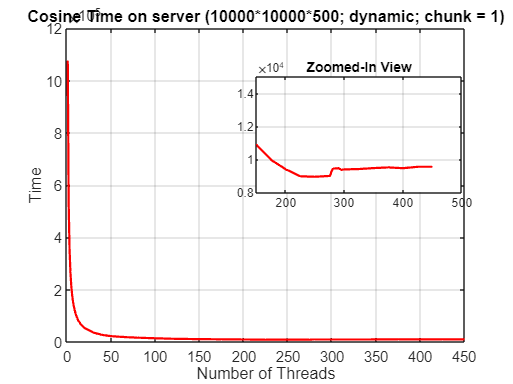

%Plot Cosine

% Data for plotting
x = ntreads_server; % X-axis values
y1 = Cosine_server;           

% Main plot
figure;                   % Open a new figure window
plot(x, y1, '-r', 'LineWidth', 1.5); hold on; % Line 1: Red

% Add labels and title
xlabel('Number of Threads');         % X-axis label
ylabel('Time');         % Y-axis label
title('Cosine Time on server (10000*10000*500; dynamic; chunk = 1)')

% Display grid on the main plot
grid on;

% Add zoomed-in inset
axes('Position', [0.5 0.5 0.4 0.3]); % Adjust position [x y width height]
box on; % Add a box around the inset
plot(x, y1, '-r', 'LineWidth', 1.5); % Plot the same data
xlim([150 500]); % Set zoomed-in x-axis range (adjust as needed)
ylim([8000 15000]); % Set zoomed-in y-axis range (adjust as needed)
title('Zoomed-In View'); % Title for the inset

% Add grid to the inset as well, if desired
grid on;